data1 = importfile1("C:\Users\asus\Desktop\MATLAB Session\data\credit_record.csv", [2, 2000]);
head(data1,3)

        ID        MONTHS_BALANCE    STATUS
    __________    ______________    ______

    5.0017e+06           0            X   
    5.0017e+06          -1            0   
    5.0017e+06          -2            0   



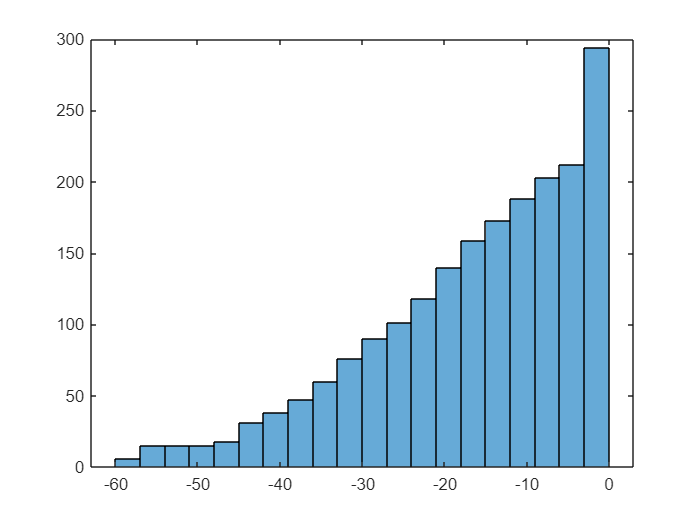

histogram(data1.MONTHS_BALANCE);

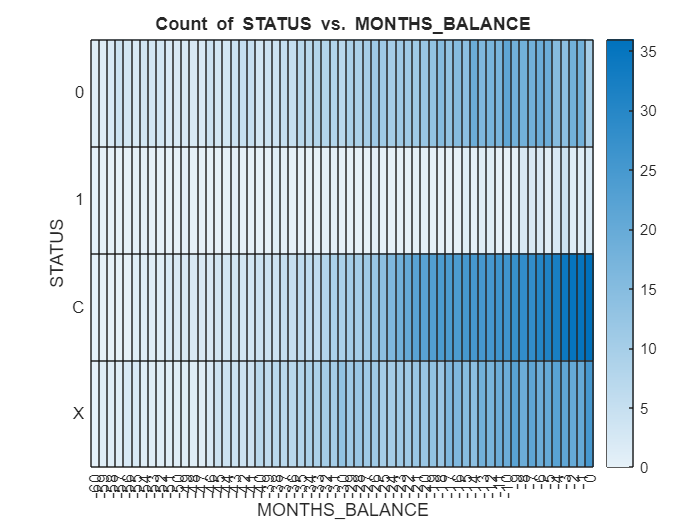

% data1 = sortrows(data1,'MONTHS_BALANCE','descend');
% head(data1,3)
heatmap(data1,"MONTHS_BALANCE","STATUS")

G = findgroups(data1{:, 1});
% Split table based on first column - gender column
T_split = splitapply( @(varargin) varargin, data1 , G);
% Allocate empty cell array fo sizxe equal to number of rows in T_Split
subTables = cell(size(T_split, 1));
% Create sub tables
for i = 1:size(T_split, 1)
subTables{i} = table(T_split{i, :}, 'VariableNames', ...
data1.Properties.VariableNames);
end

A = unique(data1.ID);


sz = [75 3];
varTypes = ["double","double","categorical"];
varNames = ["ID","MONTHS_BALANCE","STATUS"];
temps = table('Size',sz,'VariableTypes',varTypes,'VariableNames',varNames)

temps = 75×3 table
    ID    MONTHS_BALANCE      STATUS   
    __    ______________    ___________

    0           0           <undefined>
    0           0           <undefined>
    0           0           <undefined>
    0           0           <undefined>
    0           0           <undefined>
    0           0           <undefined>
    0           0           <undefined>
    0           0           <undefined>
    0           0           <undefined>
    0           0           <undefined>
    0           0           <undefined>
    0           0           <undefined>
    0           0           <undefined>
    0           0           <undefined>
    0           0           <undefined>
    0           0           <undefined>


for i = 1:length(subTables)
    [mindur,idx] = mink(subTables{i,1}.MONTHS_BALANCE,1);
    longestEmpDur = table2cell(subTables{i,1}(idx,:));
    temps(i,:) = longestEmpDur;
end

temps

temps = 75×3 table
        ID        MONTHS_BALANCE    STATUS
    __________    ______________    ______

    5.0017e+06          -3            0   
    5.0017e+06         -18            0   
    5.0017e+06         -21            X   
    5.0017e+06         -14            X   
    5.0017e+06         -59            X   
    5.0017e+06         -21            0   
    5.0017e+06         -38            X   
    5.0017e+06         -42            0   
    5.0017e+06         -35            0   
    5.0017e+06         -30            X   
    5.0017e+06         -30            X   
    5.0017e+06          -7            X   
    5.0017e+06         -38            0   
    5.0017e+06           0            0   
    5.0017e+06          -6            0   
    5.0017e+06         -60            0   


Error using tabular/join
The key variable for the right table must contain all values in the key variable for the left table.